# Using multiple linear regression to estimate PWV from age and BP

This function trains a multiple regression model to estimate aortic PWV from age and mean blood pressure (MBP). It uses data from the publicly available [Pulse Wave Database](https://peterhcharlton.github.io/pwdb/), which consists of simulated haemodynamic data (described in [this article](https://doi.org/10.1152/ajpheart.00218.2019), and available for download [here](https://doi.org/10.5281/zenodo.3275625)). This dataset contains simulated haemodynamic and pulse wave data for virtual subjects aged from 25 to 75 (in 10-year increments).

**Step 1: Load the data**

Load the PWDB data set (described in [this article](https://doi.org/10.1152/ajpheart.00218.2019), and available [here](https://doi.org/10.5281/zenodo.2633174) - the `pwdb_data.mat` file is required to run this case study).

% specify the path of the data file
up.paths.pwdb_data_file = '/Users/petercharlton/Documents/Data/Nektar1D/ageing_sims/pwdb_7/exported_data/pwdb_data.mat';

% load the data (if it hasn't already been loaded)
if ~exist('data','var')
    if ~exist(up.paths.pwdb_data_file, 'file'), error('Couldn''t locate the ''pwdb_data.mat'' file.'), end
    load(up.paths.pwdb_data_file);
end

**Step 2: Extract the required parameters**

Extract relevant data from the `data` variable.

% identify subjects with physiologically plausible data
rel_subjs = data.plausibility.plausibility_log;     % select only those subjects with physiologically plausible haemdodynamics

% extract age, MBP and PWV for these subjects
age = data.pw_inds.age(rel_subjs);
mbp = data.pw_inds.Brachial_MBP(rel_subjs);
pwv = extractfield(data.haemods, 'PWV_cf');         % extract the carotid-femoral PWV
pwv = pwv(rel_subjs); pwv = pwv(:);

The variables contain values for age, MBP and PWV from the 3,837 virtual (i.e. simulated) subjects with physiologically plausible haemodynamics.

**Step 3: Inspect the data**

Make scatter plots of PWV against age and MBP, including a least-squares best-fit line on each:

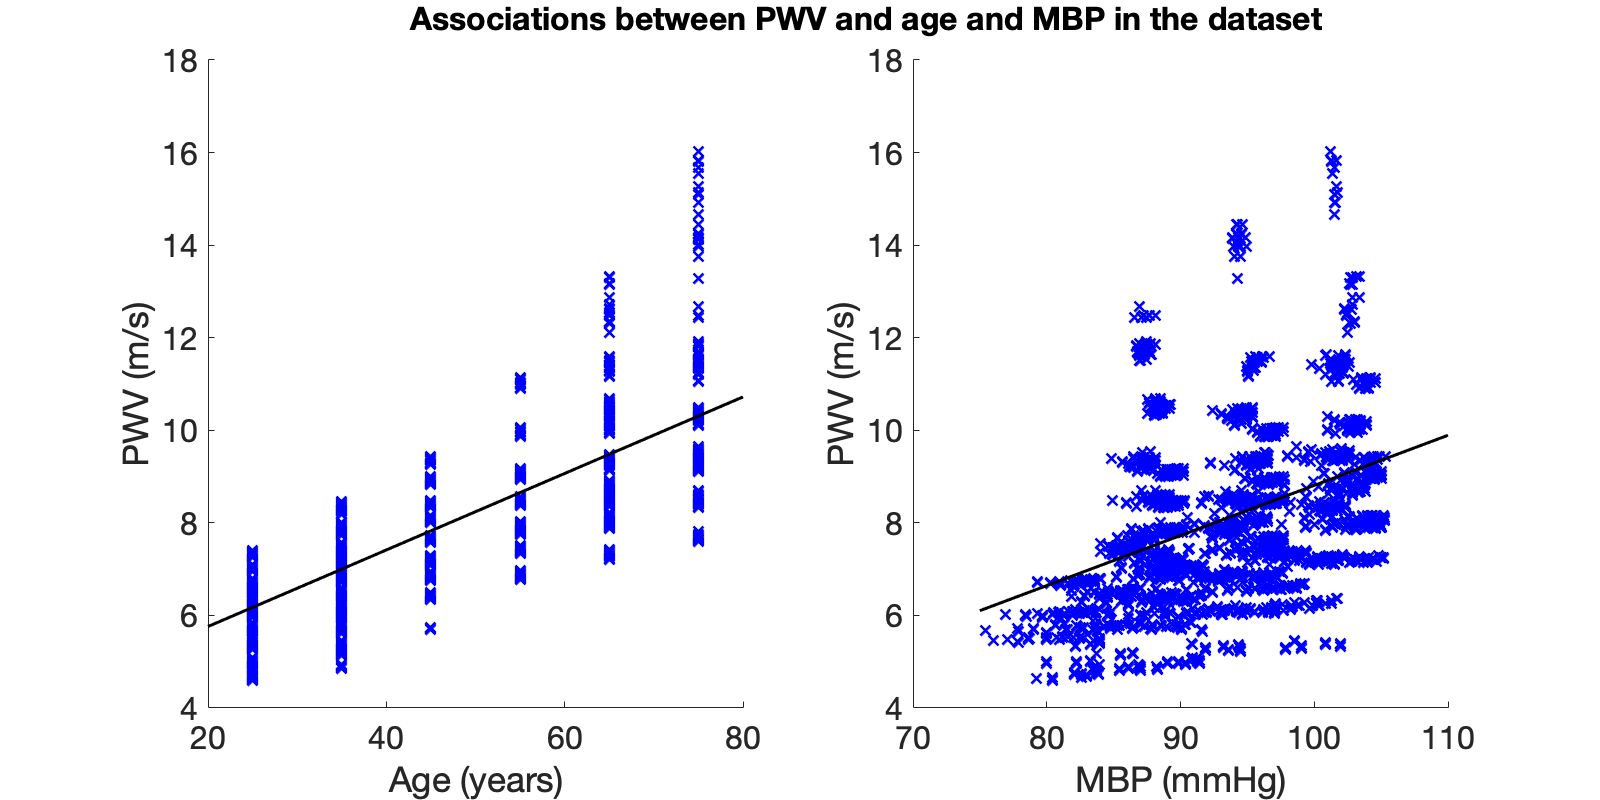

% plot options
lwidth = 1.5; ftsize = 16;
figure('Position', [20, 20, 800, 400])

% plot PWV against age
subplot(1,2,1)
plot(age, pwv, 'xb', 'LineWidth', lwidth), h = lsline;
xlabel('Age (years)', 'FontSize', ftsize)
ylabel('PWV (m/s)', 'FontSize', ftsize)
set(gca, 'FontSize', ftsize), box off, set(h, 'Color', [0,0,0], 'LineWidth', lwidth)

% plot PWV against MBP
subplot(1,2,2)
plot(mbp, pwv, 'xb', 'LineWidth', lwidth), h = lsline;
xlabel('MBP (mmHg)', 'FontSize', ftsize)
ylabel('PWV (m/s)', 'FontSize', ftsize)
set(gca, 'FontSize', ftsize), box off, set(h, 'Color', [0,0,0], 'LineWidth', lwidth)

% title
dim = [.25 .91 .1 .1];
str = 'Associations between PWV and age and MBP in the dataset';
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize,'fontweight','bold');

These plots show that in general PWV increased with age and MBP, indicating that these might be helpful predictor variables of PWV.

**Step 4: Train a multiple linear regression model**

Train a multiple linear regression model using age and MBP as predictor variables (inputs), and PWV as the response variable (output). The model specification used will have terms up to and including squared terms.

% train model
predictor_matrix = [age,mbp];
response_variable = pwv;
modelspec = 'quadratic';          % model specification (the '2' values indicate the order of terms in the model)
func = fitglm(predictor_matrix, response_variable, modelspec);   % fit model to training input and output data

**Step 5: Compare the model estimates to the true PWV values**

Use the model to calculate estimates of PWV from age and MBP:

% calculate model estimates (using Matlab function)
estimated_pwv = feval(func, predictor_matrix);
% calculate model estimates (using long-hand)
estimated_pwv2 = func.Coefficients.Estimate(1) ...
    + func.Coefficients.Estimate(2)*predictor_matrix(:,1) ...
    + func.Coefficients.Estimate(3)*predictor_matrix(:,2) ...
    + func.Coefficients.Estimate(4)*predictor_matrix(:,1).*predictor_matrix(:,2) ...
    + func.Coefficients.Estimate(5)*predictor_matrix(:,1).^2 ...
    + func.Coefficients.Estimate(6)*predictor_matrix(:,2).^2;
% these should give approximately the same answer
fprintf('Equation: PWV = %.2f + %.4f*age + %.4f*PWV + %.6f*age*PWV + %.6f*age^2 + %.6f*PWV^2', ...
    func.Coefficients.Estimate);

Equation: PWV = 1.38 + -0.0747*age + 0.0724*PWV + 0.000773*age*PWV + 0.000800*age^2 + -0.000235*PWV^2

Plot the results as a scatter plot of estimated against reference PWV, and a Bland-Altman plot showing the limits of agreement (LOAs) between the estimated and reference PWV.

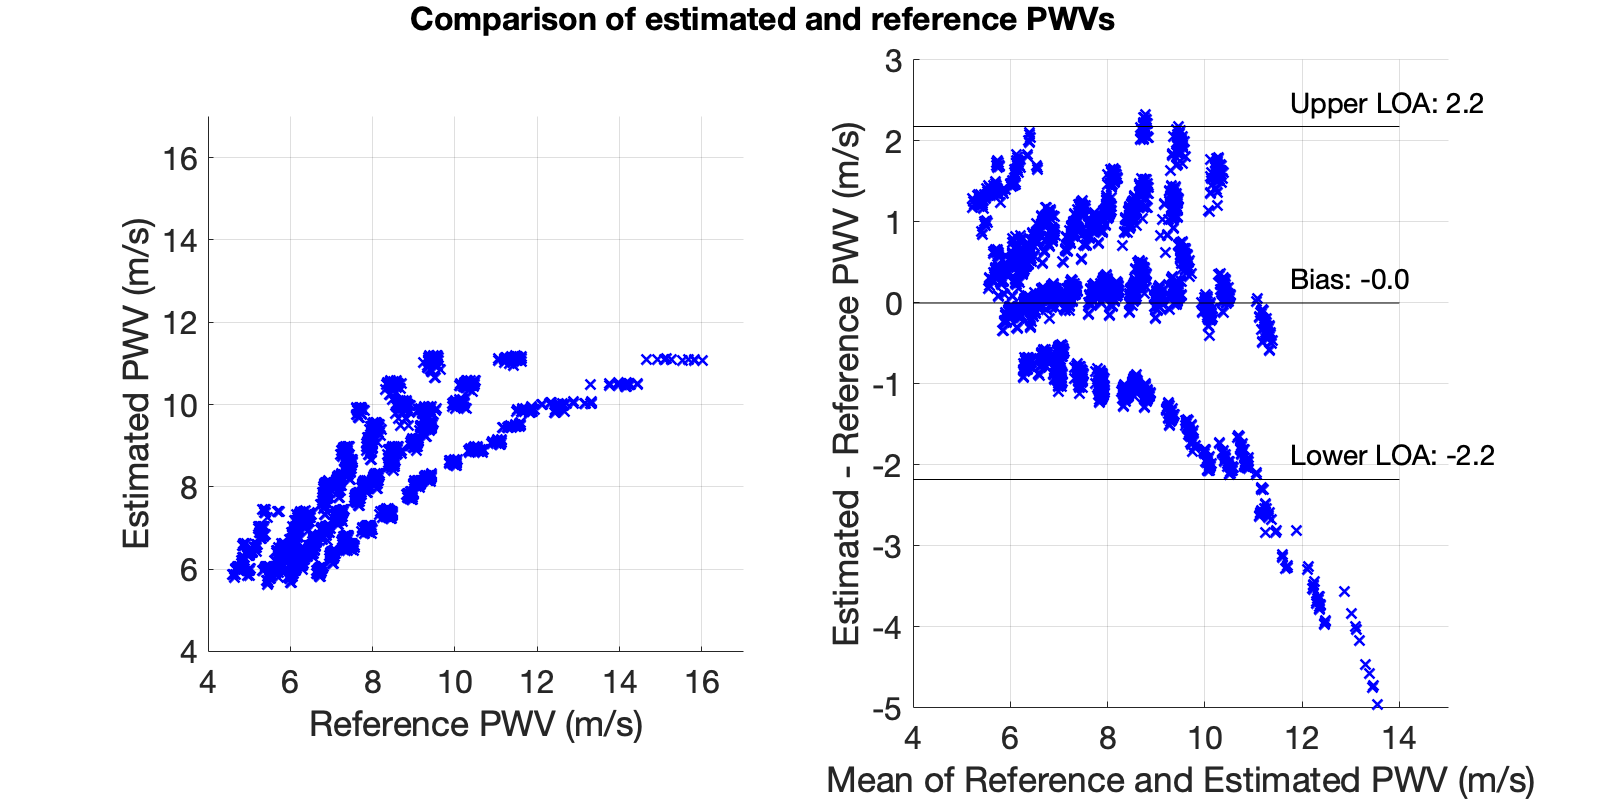

% plot options
figure('Position', [20, 20, 800, 400])

% Scatter Plot
subplot(1,2,1)
plot(pwv, estimated_pwv, 'xb', 'LineWidth', lwidth)
% - tidy up
xlabel('Reference PWV (m/s)', 'FontSize', ftsize)
ylabel('Estimated PWV (m/s)', 'FontSize', ftsize)
axis equal, grid on
lims = [floor(min([pwv; estimated_pwv])), ceil(max([pwv; estimated_pwv]))];
xlim(lims), ylim(lims)
set(gca, 'XTick', lims(1):2:lims(2), 'YTick', lims(1):2:lims(2))
set(gca, 'FontSize', ftsize), box off

% Bland-Altman plot
subplot(1,2,2)
errors = estimated_pwv-pwv;
plot(mean([pwv, estimated_pwv],2), errors, 'xb', 'LineWidth', lwidth), hold on
% - bias
bias = mean(errors);
plot(xlim, bias*ones(1,2), 'k')
dim = [.8 .58 .1 .1];
str = sprintf('Bias: %.1f', bias);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - upper loa
upper_loa = bias + 1.96*std(errors);
plot(xlim, upper_loa*ones(1,2), 'k')
dim = [.8 .8 .1 .1];
str = sprintf('Upper LOA: %.1f', upper_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - lower loa
lower_loa = bias - 1.96*std(errors);
plot(xlim, lower_loa*ones(1,2), 'k')
dim = [.8 .36 .1 .1];
str = sprintf('Lower LOA: %.1f', lower_loa);
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize - 2);
% - tidy up plot
xlabel('Mean of Reference and Estimated PWV (m/s)', 'FontSize', ftsize)
ylabel('Estimated - Reference PWV (m/s)', 'FontSize', ftsize)
set(gca, 'FontSize', ftsize, 'XTick', 4:2:15), box off, grid on

% title
dim = [.25 .91 .1 .1];
str = 'Comparison of estimated and reference PWVs';
annotation('textbox',dim,'String',str,'LineStyle','none','FontSize', ftsize,'fontweight','bold');

The Bland-Altman plot shows that the estimated PWV had minimal bias, and the limits of agreement between the estimated and reference PWV, within which 95% of errors are expected to lie, were +/- 2.2 m/s.

*Version: 0.1 (1st May 2020)*

*Copyright: Peter H Charlton (pc657@medschl.cam.ac.uk), University of Cambridge, 2020*

*Licence: Available under the GNU public license - please see the accompanying file named "LICENSE"*